## Test client to MIAerConn

Define variables

 
clear
commands = ["{""setadd"":""166.182.234.000""}",
            "{""disconnect"":""station""}",
            "{""disconnect"":""service""}"];

Connect to command channel

 

comClient = tcpclient("localhost",3000);

Send command and get the ack signal back

command = commands(2);

 
write(comClient,command);
datachr = char.empty;
waiting_for_ack = true;
while waiting_for_ack
    while isempty(datachr)
        datachr = read(comClient,comClient.NumBytesAvailable,"char");
    end
    datastr=convertCharsToStrings(datachr);
    disp("Received: "+ datastr);
    datastr=erase(datastr,"PING\r\n");
    if contains(datastr,"ACK:")
        cleanedSequence = strtrim(datastr);  % Removes leading and trailing whitespace (including CRLF)
        dataPart = extractAfter(cleanedSequence, 'ACK:');
        commandNumber = str2double(dataPart);
        message = sprintf('Command entered in queue postion: %d', commandNumber);
        waiting_for_ack = false;
    end
end

Received: ACK:1



disp(message);

Command entered in queue postion: 1


Connect to stream channel

 

streamClient = tcpclient("localhost",3001);

Get the data streamed

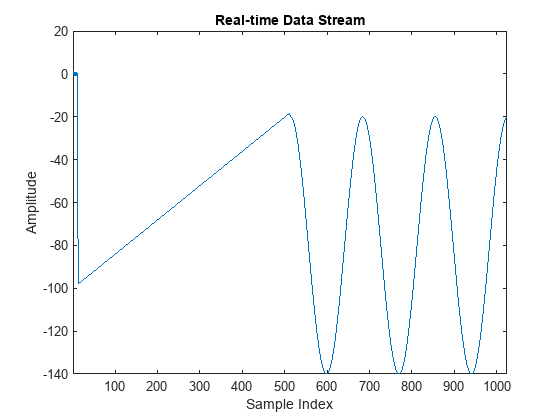

Array indices must be positive integers or logical values.

Error in basics>findBlockEndIndices (line 125)
        if isequal(buffer(i:i+blockEndLen-1), blockEnd)

 

% Define block separator (BLOCK_END)
BLOCK_END = char([39 10 13 39]);
READ_SIZE = 4100;

dataBuffer = [];
log = string([]);

% Set up the initial plot
f = uifigure;
ax = uiaxes(f);

title('Real-time Data Stream');
xlabel('Sample Index');
ylabel('Amplitude');

% Continuously receive data and update the plot
receiving_data = true;
parsing_blocks = true;

maxSearch = READ_SIZE;
blockEndLen = length(BLOCK_END);

streamClient.Timeout = 5;

while receiving_data

    try
        datastream = read(streamClient, READ_SIZE, "char");

        if isempty(datastream)
            continue
        end
        
        dataBuffer = [dataBuffer, datastream];
    catch ME
        log = [log; sprintf('Error receiving data: %s',ME.message)];
    end

    while parsing_blocks
        
        blockEndIdx = findBlockEndIndices(dataBuffer, maxSearch, BLOCK_END);
        
        % If no BLOCK_END found, break the loop and wait for more data
        if isempty(blockEndIdx)
            % expand maxSeatch to include the entire data to arrive
            maxSearch = READ_SIZE;
            break;
        end
        
        % Process each block
        for i = 1:length(blockEndIdx)
            % guess that blocks are of the same size and there is no need
            % to search beyond the size of the first block.
            maxSearch = READ_SIZE - blockEndIdx(i) - blockEndLen;

            % Extract the block data
            blockData = dataBuffer(1:blockEndIdx(i));
            
            % Remove the block to be presented from the buffer
            dataBuffer = dataBuffer(blockEndIdx(i) + blockEndLen + 1:end);
            
            % Convert the block data to single precision floats
            try
                % Make sure the block is a multiple of 4 bytes
                if mod(length(blockData), 4) == 0
                    dataFloats = typecast(uint8(blockData),"single");
                    
                    % Plot the data
                    set(h, 'YData', dataFloats);
                    set(h, 'XData',1:length(dataFloats));
                    xlim([1 length(dataFloats)]);
                    drawnow;
                else
                    log = [log;'Block with wrong number of bytes'];
                end
            catch ME
                log = [log; sprintf('Error processing block: %s',ME.message)];
            end
        end
    end
end


function indexes = findBlockEndIndices(buffer, maxSearch, blockEnd)
    % Find all occurrences of BLOCK_END in the buffer up to maxSearch element
    blockEndLen = length(blockEnd);
    searchStartIdx = length(buffer) - blockEndLen + 1;
    searchEndIdx = length(buffer) - maxSearch + 1;
    indexes = [];
    % loop from the end to the beginning to reduce the number of iterations
    for i = searchStartIdx:-1:searchEndIdx
        if isequal(buffer(i:i+blockEndLen-1), blockEnd)
            indexes = [i-1,indexes];
            if i < maxSearch
                return
            end
        end
    end
end

Test typecast

data = [0.0, 1.0, 0.0, -1.0, 0.0]; 

dataBytes = typecast(single(data), 'uint8');

trace = char(dataBytes);

disp('Encoded data:');
disp(trace);
dataBytes = uint8(trace);

% Convert the uint8 byte array back to the original single precision float array
recovedData = typecast(dataBytes, 'single');

% Display the result
disp('Recovered data:');
disp(recovedData);

Close the TCP connection if needed

clear streamClient;
